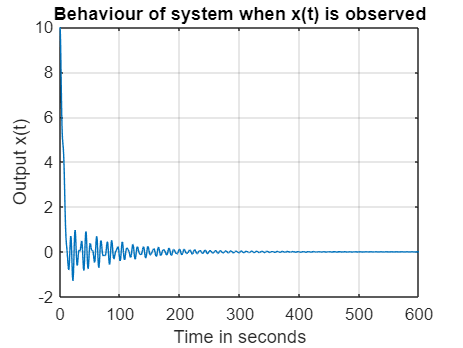

% Declaring variables to derive the state space representation of system
% M is the Mass of cart
% m1 is the mass attached to pendulum 1
% m2 is the mass attached to pendulum 2
% l1 is the length of pendulum 1
% l2 is the length of pendulum 2
% g is the accleration due to gravity 

% Declaring the values of system variables
M_val = 1000;
m1_val = 100;
m2_val = 100;
l1_val = 20;
l2_val = 10;

A_val = [0 1 0 0 0 0;
         0 0 -(m1_val*9.81)/M_val 0 -(m2_val*9.81)/M_val 0;
         0 0 0 1 0 0;
         0 0 -((M_val+m1_val)*9.81/(M_val*l1_val)) 0 -(m2_val*9.81)/(M_val*l1_val) 0;
         0 0 0 0 0 1;
         0 0 -(m1_val*9.81)/(M_val*l2_val) 0 -((M_val+m2_val)*9.81/(M_val*l2_val)) 0];

% Declaring the B matrix of the system
B_val = [0; 1/M_val; 0; 1/(M_val*l1_val); 0; 1/(M_val*l2_val)];

% Defining the Q and R matrices for LQR controller
Q = [10  0  0  0  0  0;
     0  10  0  0  0  0;
     0   0 100 0  0  0;
     0   0  0  1  0  0;
     0   0  0  0 100 0;
     0   0  0  0  0  1];

R = 0.001;

% Finding the optimal closed-loop feedback gain using LQR
K = lqr(A_val,B_val,Q,R);

D = 0;

% Defining the process and measurement noise
Vd = 0.2*eye(6);
Vn = 1;



% The controllability matrix when output vector is x(t)
C1 = [1 0 0 0 0 0];

% The controllability matrix when output vector is (x(t), theta2(t))
C3 = [1 0 0 0 0 0;
      0 0 0 0 1 0];

% The controllability matrix when output vector is (x(t), theta1(t), theta2(t))
C4 = [1 0 0 0 0 0;
      0 0 1 0 0 0;
      0 0 0 0 1 0];

% For the observability matrix after putting parameter values
ob1 = obsv(A_val, C1);
ob3 = obsv(A_val, C3);
ob4 = obsv(A_val, C4);

% The poles of the Luenberger observer
L_poles = [-4; -4.5; -5; -5.5; -6; -6.5];
% Specifying the initial condition where estimated states 
% are initialized to zero
x0 = [0;0;0.5;0;0.6;0;0;0;0;0;0;0];

% The observer gains for each observer, when the observer poles are placed
% at L_poles
L1 = place(A_val', C1', L_poles);
L3 = place(A_val', C3', L_poles);
L4 = place(A_val', C4', L_poles);

% The Luenberger observer obtained when x(t) is observed
% The initial condition
x0_obs = [10;0;0.5;0;0.6;0];

% Plotting x(t) for non-linear system when x(t) is observed
t_span = 0:0.01:600;
[ts,x_dots_L1] = ode45(@(t,x)non_lin_sys(t,x,-K*x,L1,C1),t_span,x0_obs);
figure
plot(ts,x_dots_L1(:,1))
grid
xlabel('Time in seconds')
ylabel('Output x(t)')
title('Behaviour of system when x(t) is observed')

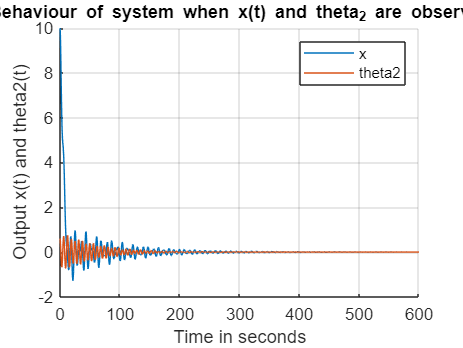




% Checking the response of system when x(t) and 
% theta2(t) are observed 
figure
hold on
[ts,x_dots_L3] = ode45(@(t,x)non_lin_sys3(t,x,-K*x,L3',C3),t_span,x0_obs);
plot(ts,x_dots_L3(:,1))
plot(ts,x_dots_L3(:,5))
grid
xlabel('Time in seconds')
ylabel('Output x(t) and theta2(t)')
title('Behaviour of system when x(t) and theta_2 are observed')
legend({'x', 'theta2'},'Location','northeast')
hold off

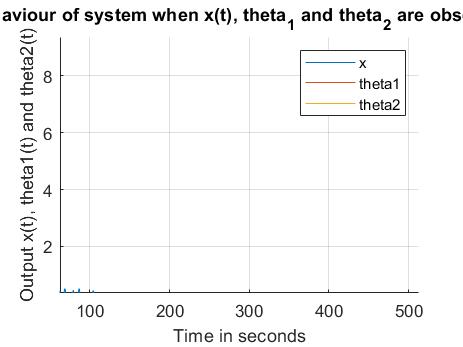


% Checking the response of system when x(t), theta1(t) and 
% theta2(t) are observed

% The response of non-linear system
% theta1 = 0.5 radians and theta2 = 0.6 radians
figure
hold on
[ts,x_dots_L4] = ode45(@(t,x)non_lin_sys4(t,x,-K*x,L4',C4),t_span,x0_obs);
plot(ts,x_dots_L4(:,1))
plot(ts,x_dots_L4(:,3))
plot(ts,x_dots_L4(:,5))
grid
xlabel('Time in seconds')
ylabel('Output x(t), theta1(t) and theta2(t)')
title('Behaviour of system when x(t), theta_1 and theta_2 are observed')
legend({'x', 'theta1', 'theta2'},'Location','northeast')
hold off

function x_dot = non_lin_sys(t,X,F,L,C)
x_dot = zeros(6,1);
% Declaring the values of system variables
M_val = 1000;
m1_val = 100;
m2_val = 100;
l1_val = 20;
l2_val = 10;
g_val = 9.81;
x = X(1);
x_d = X(2);
theta1 = X(3);
theta1_d = X(4);
theta2 = X(5);
theta2_d = X(6);
obs = L*(x-C*X);
x_dot(1) = x_d + obs(1);
x_dot(2) = (F-((m1_val*sin(theta1)*cos(theta1))+(m2_val*sin(theta2)*cos(theta2)))*g_val - (l1_val*m1_val*(x_dot(3)^2)*sin(theta1)) - (l2_val*m2_val*(x_dot(5)^2)*sin(theta2)))/(m1_val+m2_val+M_val-(m1_val*(cos(theta1)^2))-(m2_val*(cos(theta2)^2)))+obs(2);
x_dot(3) = theta1_d+obs(3);
x_dot(4) = ((cos(theta1)*x_dot(2)-g_val*sin(theta1))/l1_val) + obs(4);
x_dot(5) = theta2_d + obs(5);
x_dot(6) = (cos(theta2)*x_dot(2)-g_val*sin(theta2))/l2_val + obs(6);
end


function x_dot = non_lin_sys3(t,X,F,L,C)
x_dot = zeros(6,1);
% Declaring the values of system variables
M_val = 1000;
m1_val = 100;
m2_val = 100;
l1_val = 20;
l2_val = 10;
g_val = 9.81;

x = X(1);
dx = X(2);
theta1 = X(3);
theta1_d = X(4);
theta2 = X(5);
theta2_d = X(6);
y3 = [x; theta2];
sum = L*(y3-C*X);
x_dot(1) = dx + sum(1);
x_dot(2) = (F-((m1_val*sin(theta1)*cos(theta1))+(m2_val*sin(theta2)*cos(theta2)))*g_val - (l1_val*m1_val*(x_dot(3)^2)*sin(theta1)) - (l2_val*m2_val*(x_dot(5)^2)*sin(theta2)))/(m1_val+m2_val+M_val-(m1_val*(cos(theta1)^2))-(m2_val*(cos(theta2)^2)))+sum(2);
x_dot(3) = theta1_d+sum(3);
x_dot(4) = ((cos(theta1)*x_dot(2)-g_val*sin(theta1))/l1_val) + sum(4);
x_dot(5) = theta2_d + sum(5);
x_dot(6) = (cos(theta2)*x_dot(2)-g_val*sin(theta2))/l2_val + sum(6);
end


function x_dot = non_lin_sys4(t,X,F,L,C)
x_dot = zeros(6,1);
% Declaring the values of system variables
M_val = 1000;
m1_val = 100;
m2_val = 100;
l1_val = 20;
l2_val = 10;
g_val = 9.81;

x = X(1);
dx = X(2);
theta1 = X(3);
theta1_d = X(4);
theta2 = X(5);
theta2_d = X(6);
y4 = [x; theta1; theta2];
sum = L*(y4-C*X);
x_dot(1) = dx + sum(1);
x_dot(2) = (F-((m1_val*sin(theta1)*cos(theta1))+(m2_val*sin(theta2)*cos(theta2)))*g_val - (l1_val*m1_val*(x_dot(3)^2)*sin(theta1)) - (l2_val*m2_val*(x_dot(5)^2)*sin(theta2)))/(m1_val+m2_val+M_val-(m1_val*(cos(theta1)^2))-(m2_val*(cos(theta2)^2)))+sum(2);
x_dot(3) = theta1_d+sum(3);
x_dot(4) = ((cos(theta1)*x_dot(2)-g_val*sin(theta1))/l1_val) + sum(4);
x_dot(5) = theta2_d + sum(5);
x_dot(6) = (cos(theta2)*x_dot(2)-g_val*sin(theta2))/l2_val + sum(6);
end